tau = 0.05

tau = 0.0500

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



alpha = (s*tau + 1)^2

alpha =
 
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.




beta = (0.05*s + 1)^4 / 0.9

beta =
 
  6.25e-06 s^4 + 0.0005 s^3 + 0.015 s^2 + 0.2 s + 1
  -------------------------------------------------
                         0.9
 
Continuous-time transfer function.




GHsym = [s/alpha, -1/alpha, -1/alpha, 0;
         s/alpha, (alpha - 1/alpha)/s^2, -1/(s^2 * alpha), 1/s^2;
         (1-s/alpha)/beta, -(alpha-1/alpha)/(beta * s^2), 1/(beta*s^2*alpha), -1/(beta*s^2);
         s/(beta*alpha), (1-1/alpha)/beta, -1/(beta*alpha), 0]

GHsym =
 
  From input 1 to output...
                 s
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                 s
   2:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                                   0.00225 s^2 - 0.81 s + 0.9
   3:  -----------------------------------------------------------------------------------
       1.563e-08 s^6 + 1.875e-06 s^5 + 9.375e-05 s^4 + 0.0025 s^3 + 0.0375 s^2 + 0.3 s + 1
 
                                              0.9 s
   4:  -----------------------------------------------------------------------------------
       1.563e-08 s^6 + 1.875e-06 s^5 + 9.375e-05 s^4 + 0.0025 s^3 + 0.0375 s^2 + 0.3 s + 1
 
  From input 2 to output...
                 -1
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
       6.25e-06 s^4 + 0.0005 s^3 + 0.015 s^2 + 0.2 s
   2:  ---------------------------------------------
                0.0025 s^4 + 0.1 s^3 + s^2
 
                         -5.625e-06 s^4 - 0.00045 s^3 - 0



Gss_q1 = ss(GHsym, 'minimal')

Gss_q1 =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12
   x1     -13.19     23.25     11.24    -29.18    -3.221    0.9772    -1.054     -5.58     1.226    -6.036    -1.219    -3.976
   x2     -6.894    -6.386    -19.72     33.87     21.48    -7.264    -7.961    0.2783     1.441     -1.58     1.141     11.74
   x3     -1.758     3.508    -6.012      8.37     18.92     -6.34    -26.61     2.841    0.1851     1.306     3.585     9.603
   x4      6.273    -1.667     19.54    -30.55    -40.23     13.56     45.67    -4.457     -1.12    -1.012    -5.971    -20.64
   x5    -0.1795   0.04771  -0.02725     -0.76    -11.63     3.815     27.97     1.319     3.451    -2.013     2.056    -2.075
   x6     0.1284  -0.03413    0.0195   -0.0178     3.839    -1.325    -9.431   -0.4651      -1.2     0.696   -0.7273    0.6345
   x7        -10     2.658    -1.518     1.386     2.477   -0.7152    -23.98     0.315    0.1

% SS


E1 = [1, 0, 0, 0, 0, 0;
     0, 1, 0, 0, 0, 0;
     0, 0, 1, 0, 0, -tau^2;
     0, 0, 0, 1, -tau^2, 0;
     0, 0, 0, -1/tau^2, 1, 0;
     0, 0, -1/tau^2, 0, 0, 1]

E1 =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0   -0.0025
         0         0         0    1.0000   -0.0025         0
         0         0         0 -400.0000    1.0000         0
         0         0 -400.0000         0         0    1.0000



A1 = [0, 0, 0, 1, 0, 0;
      0, 0, 0, 0, 0, 1;
      0, 1, 0, 0, 0, 2*tau;
      0, 1, 0, 0, 2*tau, 0;
      0, -1/tau^2, 0, 0, -2/tau, 0;
      0, -1/tau^2, 0, 0, 0, -2/tau]

A1 =          0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000
         0    1.0000         0         0         0    0.1000
         0    1.0000         0         0    0.1000         0
         0 -400.0000         0         0  -40.0000         0
         0 -400.0000         0         0         0  -40.0000



B1 = [0, 0, 0, 0;
      0, 0 ,0 ,0;
      0, 1, 1, 0;
      0, 1, 0, 1;
      0, -1/tau^2, 0, -1/tau^2;
      0, -1/tau^2, -1/tau^2, 0]

B1 =          0         0         0         0
         0         0         0         0
         0    1.0000    1.0000         0
         0    1.0000         0    1.0000
         0 -400.0000         0 -400.0000
         0 -400.0000 -400.0000         0



L = [0, 1, 0, 0;
     0, 0, 1, 0;
     0, 0, 0, 1;
     -16, -32, -24, -8]

L =      0     1     0     0
     0     0     1     0
     0     0     0     1
   -16   -32   -24    -8



A2 = [L, zeros(4);
      zeros(4), L]

A2 =      0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
   -16   -32   -24    -8     0     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1
     0     0     0     0   -16   -32   -24    -8



zr4 = zeros(1,4);
B2 = [zr4; zr4; zr4;
      16, 0, 0, 0;
      zr4; zr4; zr4;
      0, 16, 0, 0]

B2 =      0     0     0     0
     0     0     0     0
     0     0     0     0
    16     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0    16     0     0



zr6 = zeros(1,6);

W = [zr6; zr6; zr6;
    -16, 0, zr4;
    zr6; zr6; zr6;
    0, 16, zr4]

W =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
   -16     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0    16     0     0     0     0



Ap = [A1, zeros(6, 8);
     W, A2]

Ap =          0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0    0.1000         0         0         0         0         0         0         0         0
         0    1.0000         0         0    0.1000         0         0         0         0         0         0         0         0         0
         0 -400.0000         0         0  -40.0000         0         0         0         0         0         0         0         0         0
         0 -400.0000         0         0         0  -40.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0
        


Bp = [B1;
     B2]

Bp =          0         0         0         0
         0         0         0         0
         0    1.0000    1.0000         0
         0    1.0000         0    1.0000
         0 -400.0000         0 -400.0000
         0 -400.0000 -400.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
   16.0000         0         0         0



E = [E1, zeros(6,8);
    zeros(8,6), eye(8)]

E =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0   -0.0025         0         0         0         0         0         0         0         0
         0         0         0    1.0000   -0.0025         0         0         0         0         0         0         0         0         0
         0         0         0 -400.0000    1.0000         0         0         0         0         0         0         0         0         0
         0         0 -400.0000         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0
         


% this is zero which doesnt seem good
det(E)

ans = 0


% continue on to get C and D
C = [0, 1, zr6, zr6;
     1, 0, zr6, zr6;
     zr6, 1, 0, zr6;
     zr6, zr4, 1, 0, 0, 0]

C =      0     1     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0


D = 0

D = 0

GH = dss(Ap, Bp, C, D, E)

GH =
 
  A = 
          x1    x2    x3    x4    x5    x6    x7    x8    x9   x10   x11   x12   x13   x14
   x1      0     0     0     1     0     0     0     0     0     0     0     0     0     0
   x2      0     0     0     0     0     1     0     0     0     0     0     0     0     0
   x3      0     1     0     0     0   0.1     0     0     0     0     0     0     0     0
   x4      0     1     0     0   0.1     0     0     0     0     0     0     0     0     0
   x5      0  -400     0     0   -40     0     0     0     0     0     0     0     0     0
   x6      0  -400     0     0     0   -40     0     0     0     0     0     0     0     0
   x7      0     0     0     0     0     0     0     1     0     0     0     0     0     0
   x8      0     0     0     0     0     0     0     0     1     0     0     0     0     0
   x9      0     0     0     0     0     0     0     0     0     1     0     0     0     0
   x10   -16     0     0     0     0     0   -16   -32   -24    -8     0    

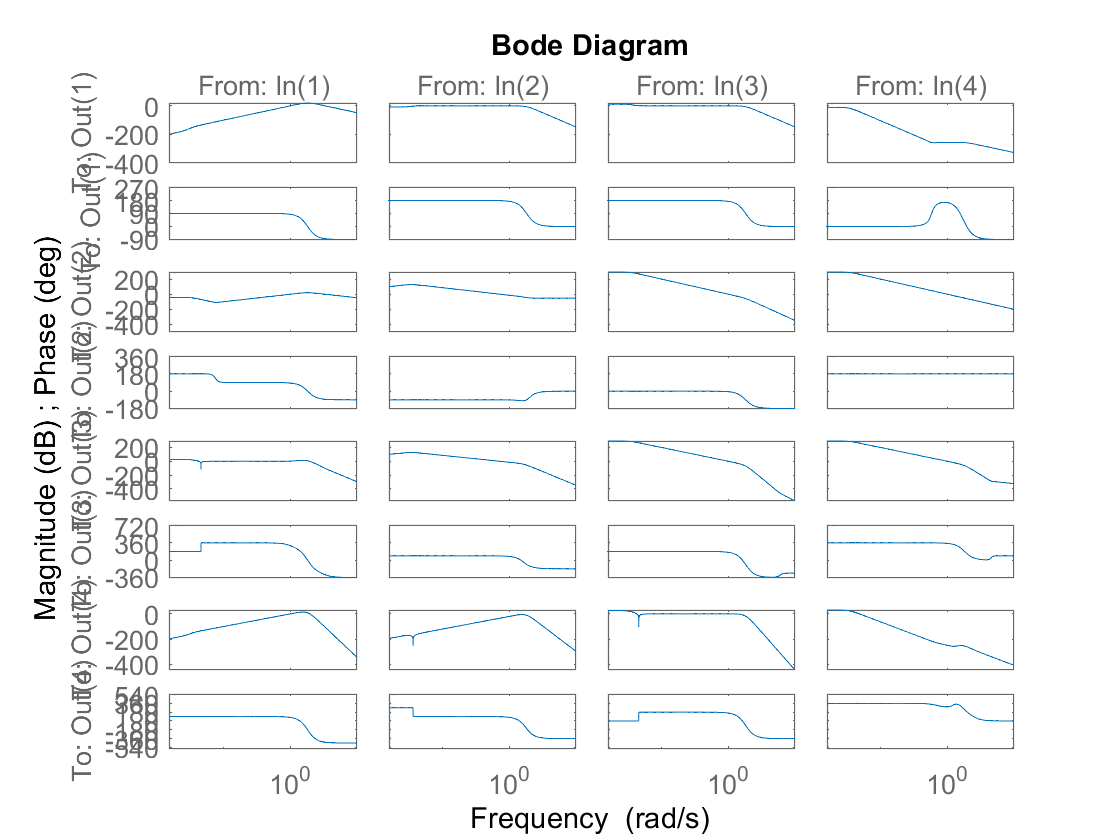


bode(Gss_q1)

% realised that matlab uses [z; y] when the q1 has asked for [y; z]

% form subsystem from r to e
A =  Gss_q1.A

A =   -13.1925   23.2496   11.2402  -29.1846   -3.2205    0.9772   -1.0543   -5.5798    1.2263   -6.0361   -1.2192   -3.9761    2.6399    2.8571
   -6.8938   -6.3860  -19.7216   33.8700   21.4773   -7.2638   -7.9611    0.2783    1.4414   -1.5796    1.1407   11.7376  -21.1657  -12.2828
   -1.7577    3.5083   -6.0117    8.3705   18.9221   -6.3399  -26.6075    2.8406    0.1851    1.3061    3.5854    9.6026  -27.4815  -16.2059
    6.2730   -1.6675   19.5408  -30.5484  -40.2263   13.5607   45.6708   -4.4566   -1.1196   -1.0119   -5.9714  -20.6383   53.3151   31.7729
   -0.1795    0.0477   -0.0273   -0.7600  -11.6258    3.8145   27.9714    1.3194    3.4512   -2.0127    2.0559   -2.0754   21.4471   22.0079
    0.1284   -0.0341    0.0195   -0.0178    3.8388   -1.3250   -9.4315   -0.4651   -1.1999    0.6960   -0.7273    0.6345   -7.2206   -7.4879
  -10.0005    2.6583   -1.5183    1.3861    2.4770   -0.7152  -23.9830    0.3150    0.1063    0.8959    0.2583   -0.1476    7.1937   10.8018
    4.910

Bs = Gss_q1.B(:, 1:2);
Cs = Gss_q1.C(3:4, :);
Ds = Gss_q1.D(3:4, 1:2);

gamma = 0.1; % for example

n = size(A,1);
m = size(Bs,2);
p = size(Cs,1);

% LMIs
setlmis([]);

P = lmivar(1,[n 1]);

lmi1 = newlmi;

% Schur component
%   [ A^T P + P A,   P B,        C^T
%     B^T P,         -gamma^2 I, D^T
%     C,             D,          -gamma^2 I ] < 0

% 'lmiterm([lmi row col X], A, B, flag)' means "place A*X*B into (row,col)
% block

% (1,1) A^T P + P A
lmiterm([lmi1 1 1 P], A', 1, 's');  
% The 's' flag makes it add the symmetric term P*A.

% (2,2) block: -gamma^2 I (dimension m×m)
lmiterm([lmi1 2 2 0], -gamma^2*eye(m));

% (3,3) block: -gamma^2 I (dimension p×p)
lmiterm([lmi1 3 3 0], -gamma^2*eye(p));

% (1,2) block: P B
lmiterm([lmi1 1 2 P], 1, Bs);  

% (2,1) block: B^T P
lmiterm([lmi1 2 1 P], Bs', 1);

% (1,3) block: C^T
lmiterm([lmi1 1 3 0], Cs');

% (3,1) block: C
lmiterm([lmi1 3 1 0], Cs);

% (2,3) block: D^T
lmiterm([lmi1 2 3 0], Ds');

% (3,2) block is the transpose: D
lmiterm([lmi1 3 2 0], Ds);

% need another LMI
lmi2 = newlmi;
% P > 0
lmiterm([lmi2 1 1 P], 1, 1);
% definition of LMIs should be done


lmisys = getlmis;

options = [0 0 0 0 1];
[tmin, xfeas] = feasp(lmisys, options);

if tmin 
    disp('A feasible P was found => ||G||_inf < gamma');
    % calc P matrix
    Psol = dec2mat(lmisys, xfeas, P);
    disp('P = '), disp(Psol)
else
    disp('No feasible solution => cannot conclude ||G||_inf < gamma');
end

A feasible P was found => ||G||_inf < gamma


P = 
   1.0e+06 *

  Columns 1 through 13

   -0.0003    0.0147    0.0413    0.0277    0.0061    0.0223    0.0003   -0.0002   -0.0001    0.0000   -0.0000    0.0000   -0.0000
    0.0147   -0.8549   -2.4056   -1.6128   -0.3526   -1.2963   -0.0155    0.0099    0.0084   -0.0022    0.0011   -0.0009    0.0016
    0.0413   -2.4056   -6.7697   -4.5386   -0.9922   -3.6479   -0.0437    0.0279    0.0235   -0.0061    0.0031   -0.0025    0.0046
    0.0277   -1.6128   -4.5386   -3.0428   -0.6652   -2.4457   -0.0293    0.0187    0.0158   -0.0041    0.0021   -0.0017    0.0031
    0.0061   -0.3526   -0.9922   -0.6652   -0.1454   -0.5347   -0.0064    0.0041    0.0035   -0.0009    0.0005   -0.0004    0.0007
    0.0223   -1.2963   -3.6479   -2.4457   -0.5347   -1.9657   -0.0235    0.0150    0.0127   -0.0033    0.0017   -0.0013    0.0025
    0.0003   -0.0155   -0.0437   -0.0293   -0.0064   -0.0235   -0.0003    0.0002    0.0002   -0.0000    0.0000   -0.0000    0.0000
   -0.0002    0.0099    0.0279    0.0187

ny = 2;
nz = 2;
new_order = [ny+1 : ny+nz, 1 : ny];

Gss = ss(Gss_q1.A, Gss_q1.B, Gss_q1.C(new_order, :), Gss_q1.D(new_order, :));

[K, CL, gamma, info] = hinfsyn(Gss, 2, 2);
disp(gamma);

    0.9068



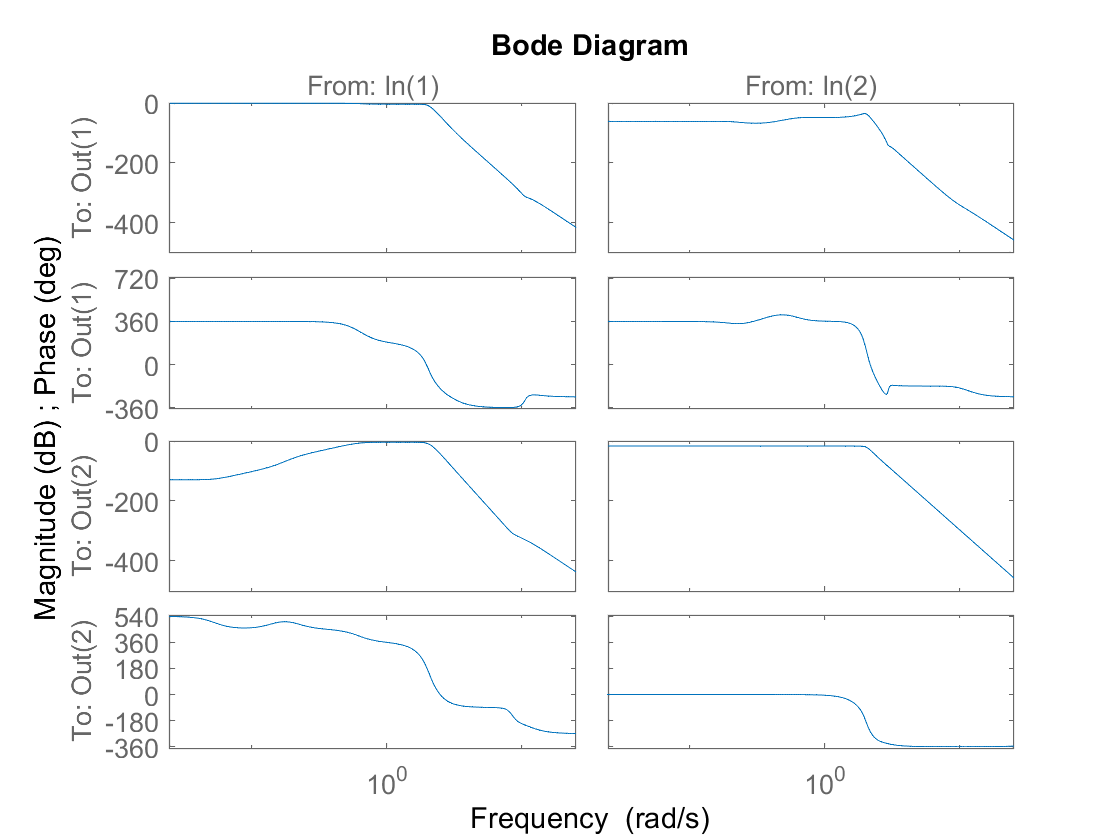

% step response, harmonic - low frequency, harmonic - high frequency
figure; grid on;
bode(CL);

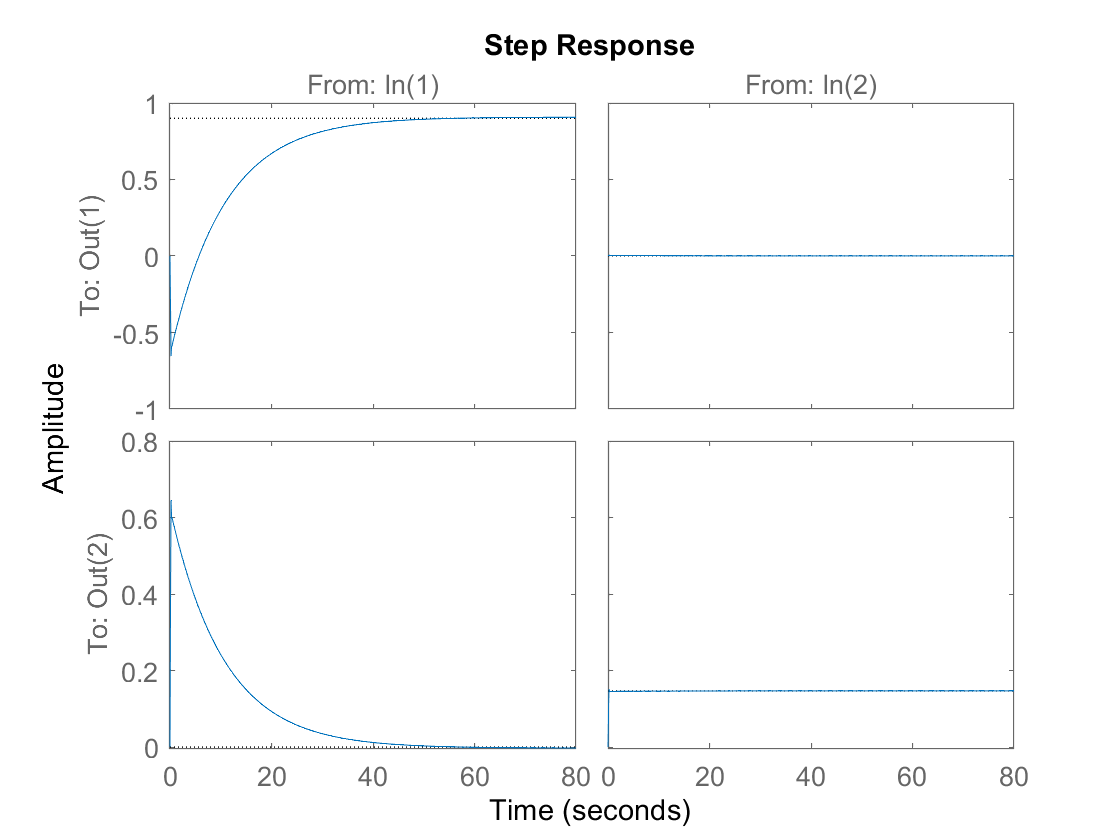


figure; grid on;
step(CL);

## c) uncertainty

blk = [1, 0; 1, 0];
[Bounds, mussvInfo] = mussv(CL, blk);

Computing bounds... Points completed: 62/62
Computing peak...  Percent completed: 100/100


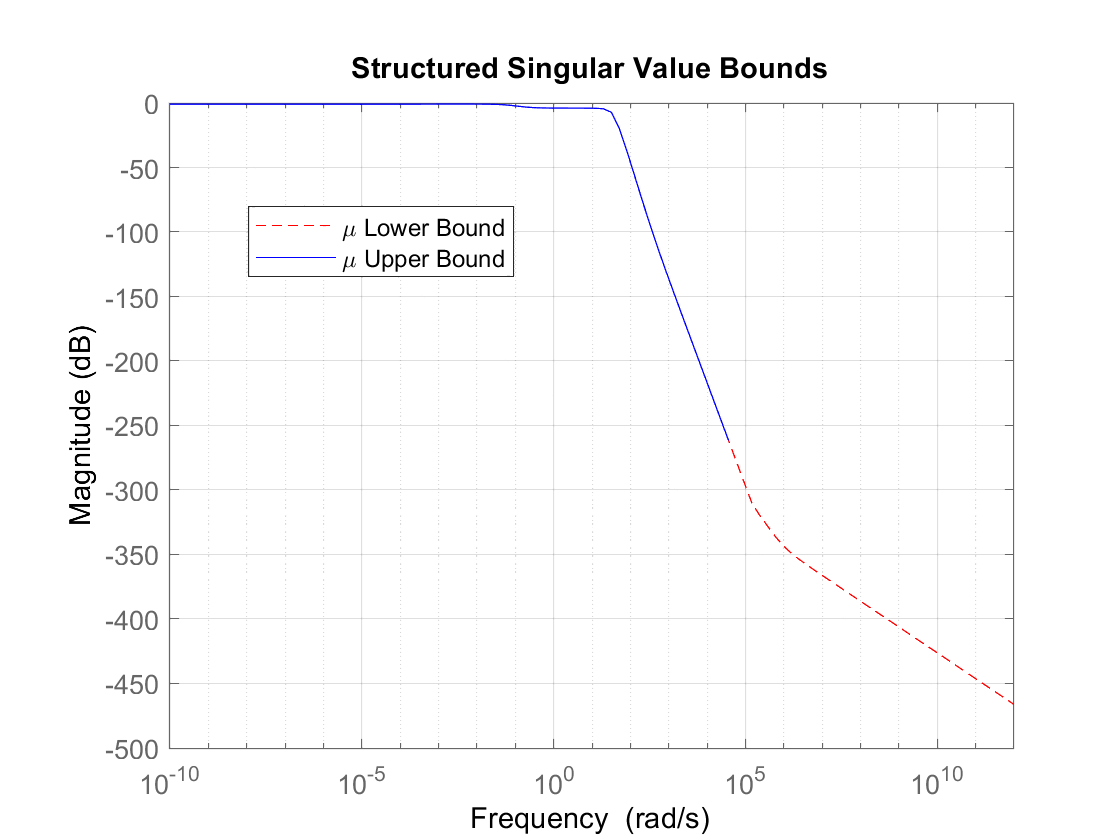

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



sigmaLower = Bounds(:,1);
sigmaUpper = Bounds(:,2);
    
figure; 
bodemag(sigmaLower, 'r--', sigmaUpper, 'b-'); 
grid on
legend('\mu Lower Bound','\mu Upper Bound','Location','Best')
title('Structured Singular Value Bounds')

## passive

% system definition

tau = 0.05

tau = 0.0500

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



alpha = (s*tau + 1)^2

alpha =
 
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.




beta = (1 - 1/alpha)

beta =
 
    0.0025 s^2 + 0.1 s
  ----------------------
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.




GHpsym = [1/s, 1/(s*alpha), 1/s, 0;
          1/(s*alpha), 1/s, 0, 1/s;
          beta/s^2, -beta/s^2, 1/s^2, -1/s^2;
          beta/s, -beta/s, 1/s, -1/s]

GHpsym =
 
  From input 1 to output...
       1
   1:  -
       s
 
                  1
   2:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
           0.0025 s^2 + 0.1 s
   3:  --------------------------
       0.0025 s^4 + 0.1 s^3 + s^2
 
          0.0025 s^2 + 0.1 s
   4:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
  From input 2 to output...
                  1
   1:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
       1
   2:  -
       s
 
          -0.0025 s^2 - 0.1 s
   3:  --------------------------
       0.0025 s^4 + 0.1 s^3 + s^2
 
         -0.0025 s^2 - 0.1 s
   4:  ------------------------
       0.0025 s^3 + 0.1 s^2 + s
 
  From input 3 to output...
       1
   1:  -
       s
 
   2:  0
 
        1
   3:  ---
       s^2
 
       1
   4:  -
       s
 
  From input 4 to output...
   1:  0
 
       1
   2:  -
       s
 
       -1
   3:  ---
       s^2
 
       -1
   4:  --
       s
 
Continuous-time transfer function.




Gss_q2 = ss(GHpsym, 'minimal')

Gss_q2 =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1       -31.3     -0.9265       3.481      -5.063      -30.72      -8.603       3.003
   x2      -12.77      -2.799    -0.06832       13.55      -6.945       1.233     -0.3366
   x3      -4.701       -2.11     -0.9947       10.14      -0.767        1.66     -0.5946
   x4   -0.005161   -0.002154  -0.0008383      -33.05      -13.62    -0.02876     -0.0447
   x5  -0.0007032  -0.0002935  -0.0001142       12.52      -6.943     0.01251     0.02049
   x6       11.61       4.844       1.885      -24.74       1.938      -4.407       1.487
   x7      -4.004      -1.671     -0.6504       8.537     -0.6691       1.521     -0.5129
 
  B = 
               u1          u2          u3          u4
   x1      -1.402       7.518     0.09296    -0.09973
   x2       1.613       2.221     -0.4984      0.5316
   x3       1.427      0.5045     -0.8684       0.926
   x4      -7.333     -0.1863    0.00

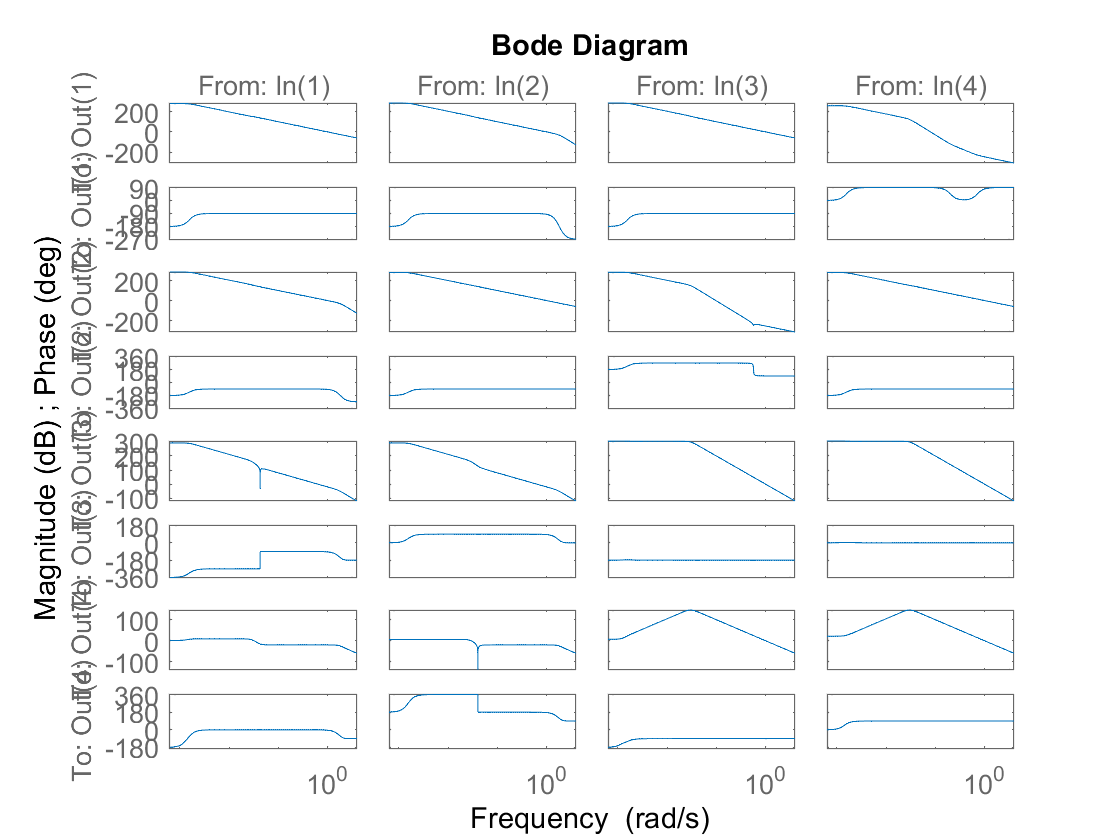


bode(Gss_q2)

% bounded gain LMI is near identical to before

% form subsystem from f to e
A = Gss_q2.A

A =   -31.2967   -0.9265    3.4812   -5.0635  -30.7180   -8.6028    3.0026
  -12.7651   -2.7991   -0.0683   13.5484   -6.9447    1.2330   -0.3366
   -4.7009   -2.1100   -0.9947   10.1387   -0.7670    1.6596   -0.5946
   -0.0052   -0.0022   -0.0008  -33.0464  -13.6238   -0.0288   -0.0447
   -0.0007   -0.0003   -0.0001   12.5169   -6.9427    0.0125    0.0205
   11.6069    4.8440    1.8852  -24.7449    1.9377   -4.4075    1.4867
   -4.0042   -1.6711   -0.6504    8.5366   -0.6691    1.5205   -0.5129


Bs = Gss_q2.B(:, 1:2);
Cs = Gss_q2.C(3:4, :);
Ds = Gss_q2.D(3:4, 1:2);

n = size(A,1);
m = size(Bs,2);
p = size(Cs,1);

setlmis([]);

P = lmivar(1,[n 1]);
gamma = 0.1;

lmi1 = newlmi;
% Same LMI from before for bounded gain
%   [ A^T P + P A,   P B,        C^T
%     B^T P,         -gamma^2 I, D^T
%     C,             D,          -gamma^2 I ] < 0
lmiterm([lmi1 1 1 P], A', 1, 's');  
lmiterm([lmi1 2 2 0], -gamma^2*eye(m));
lmiterm([lmi1 3 3 0], -gamma^2*eye(p));
lmiterm([lmi1 1 2 P], 1, Bs);  
lmiterm([lmi1 2 1 P], Bs', 1);
lmiterm([lmi1 1 3 0], Cs');
lmiterm([lmi1 3 1 0], Cs);
lmiterm([lmi1 2 3 0], Ds');
lmiterm([lmi1 3 2 0], Ds);
% second LMI from before
lmi2 = newlmi;
% P > 0
lmiterm([lmi2 1 1 P], 1, 1);

% PASSIVITY LMI
A = Gss_q2.A;
B = Gss_q2.B;
C = Gss_q2.C;
D = Gss_q2.D;

% [ -(AQ + QA'), QC'-B ;
%   CQ - B', D + D' ] < 0

n = size(A,1);
m = size(B,2);
p = size(C,1);

Q = lmivar(1,[n 1]);
epsilon = 0.1;

lmi3 = newlmi;

lmiterm([lmi3 1 1 Q], -A, 1, 's');
lmiterm([lmi3 2 2 0], D);
lmiterm([lmi3 2 2 0], D');
lmiterm([lmi3 1 2 Q], 1, C');
lmiterm([lmi3 1 2 0], -B);
lmiterm([lmi3 2 1 Q], C, 1);
lmiterm([lmi3 2 1 0], -B');

lmi4 = newlmi;
% Q > 0
lmiterm([lmi4 1 1 Q], 1, 1);

plmisys = getlmis;

options = [0 0 0 0 1];
[tmin, xfeas] = feasp(plmisys, options);

if tmin 
    disp('A feasible P was found => ||G||_inf < gamma');
    % calc P matrix
    P_sol = dec2mat(plmisys, xfeas, P);
    Q_sol = dec2mat(plmisys, xfeas, Q);
    disp('P = '), disp(P_sol)
    disp('Q = '), disp(Q_sol)
else
    disp('No feasible solution => cannot conclude ||G||_inf < gamma');
end

A feasible P was found => ||G||_inf < gamma


P = 
   1.0e+05 *

   -0.0309    0.1650    0.2875   -0.0002    0.0000    0.2064   -0.0240
    0.1650   -0.8822   -1.5365    0.0009   -0.0000   -1.1033    0.1281
    0.2875   -1.5365   -2.6761    0.0015   -0.0000   -1.9216    0.2231
   -0.0002    0.0009    0.0015    0.0000    0.0000    0.0011   -0.0001
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.2064   -1.1033   -1.9216    0.0011   -0.0000   -1.3798    0.1602
   -0.0240    0.1281    0.2231   -0.0001    0.0000    0.1602   -0.0186



Q = 
   1.0e+03 *

   -7.5916   -2.8091   -0.9408   -1.5700    0.3584    2.3385   -0.7998
   -2.8091   -2.8182   -1.5945    1.8081   -1.1899    3.8997   -1.3433
   -0.9408   -1.5945   -0.9913    1.4796   -0.8796    2.4151   -0.8330
   -1.5700    1.8081    1.4796   -3.7869    1.9316   -3.5911    1.2365
    0.3584   -1.1899   -0.8796    1.9316   -1.0678    2.1441   -0.7380
    2.3385    3.8997    2.4151   -3.5911    2.1441   -5.8963    2.0331
   -0.7998   -1.3433   -0.8330    1.2365   -0.7380    2.0331   -0.7010




ny = 2;
nz = 2;
new_order = [ny+1 : ny+nz, 1 : ny];

Gpss = ss(Gss_q2.A, Gss_q2.B, Gss_q2.C(new_order, :), Gss_q2.D(new_order, :));

[Kp, CLp, gamma_p, info_p] = hinfsyn(Gss, 2, 2);
disp(gamma_p);

    0.9068



bode(CLp)


step(CLp)